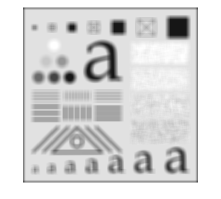

img = imread("TestPattern.tif");
img = im2double(img);
krn = ones(21)/(21^2);
imgRes = filter2(krn,img,'same');
imshow(imgRes)

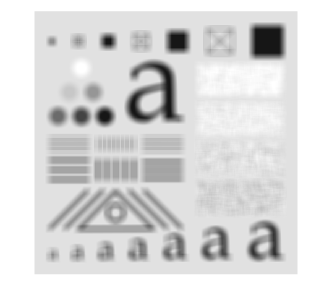


imgResPadd = imfilter(img,krn,'replicate');
imshow(imgResPadd);

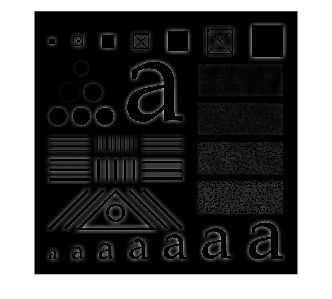


hp = zeros(21,21);
hp(11,11) = 1;
hp = hp - krn;

imgHPRes = imfilter(img,hp,'replicate');
imshow(imgHPRes);

mean(imgHPRes,"all")

ans = -5.4627e-06

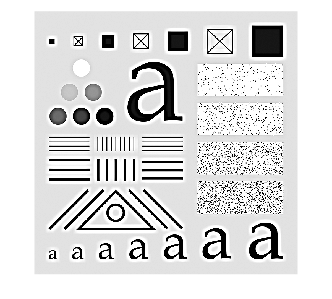


imgUnsharpMsk = img + imgHPRes;
imshow(imgUnsharpMsk);

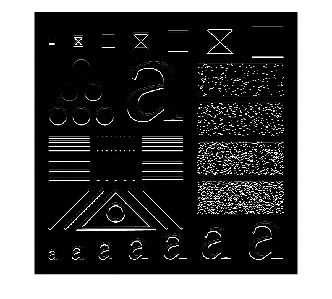

img = imread("TestPattern.tif");
img = im2double(img);
Sobx = [-1,-2,-1;0,0,0;1, 2, 1];
Soby = [-1,0,1;-2,0,2;-1, 0, 1];
krn = ones(21)/(21^2);

img6 =filter2(Sobx,img,'same');
img7 = filter2(Soby,img,'same');

imshow(img6);

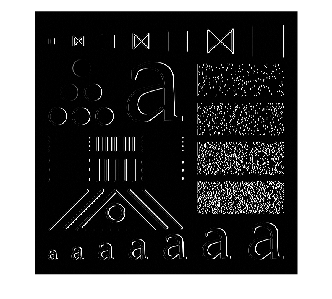

imshow(img7);

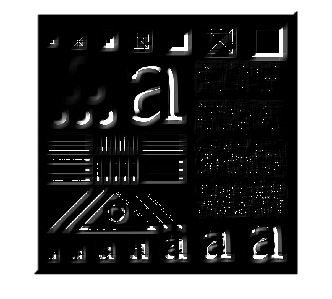


img6lp = imfilter(img6,krn,'replicate');
img7lp = imfilter(img7,krn,'replicate');
img8lp = img6lp + img7lp;
img8 =img8lp./img;
imshow(img8);

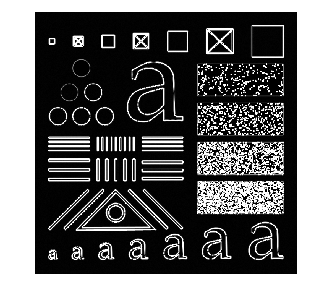


img8 = sqrt(img6.^2+ img7.^2);
imshow(img8);